clear;
clc;

load('data\filtering_data_no_downsampling.mat');
g = 9.80665;
i = 0;

% gamma——Stribeck摩擦力模型模式选择
%     gamma = 1 —— Tustin 模型
%     gamma = 2 —— Gaussian 指数模型
gamma = 2;

## 准备

addpath '.\utils';
addpath '.\two-step\';
addpath '.\two-step\verify\';
[n_sample, ~] = size(q_filt);
n_parameters = 43;
ww = zeros(n_sample * 7, n_parameters);

for k = 1 : n_sample
    q = q_filt(k, :);
    qd = qd_filt(k, :);
    qdd = qdd_filt(k, :);

    start_row = 1 + (k - 1) * 7;
    end_row = k * 7;

    if n_parameters == 43 
        flag = 0;
    else
        flag = 1;
    end

    ww(start_row : end_row, :) = compute_regression_matrix(q, qd, qdd, flag);
end

## 第一步：辨识惯性参数

opt_x0 = zeros(91, 1);
object = @Optimal_object_first_step;
nonlcon = @Optimize_constraints_first_step;

options = optimoptions(@fmincon, 'MaxIterations', 200000, 'MaxFunctionEvaluations', 200000);
[opt_x1, opt_fval1] = fmincon(object, opt_x0, [], [], [], [], [], [], nonlcon, options);


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>


## 第一步：后处理

base_inertial_parameters = transform_parameters(opt_x1);
torque_identified = reshape(ww * base_inertial_parameters', 7, [])';
error_for_friction = t_filt - torque_identified;

## 第一步：验证

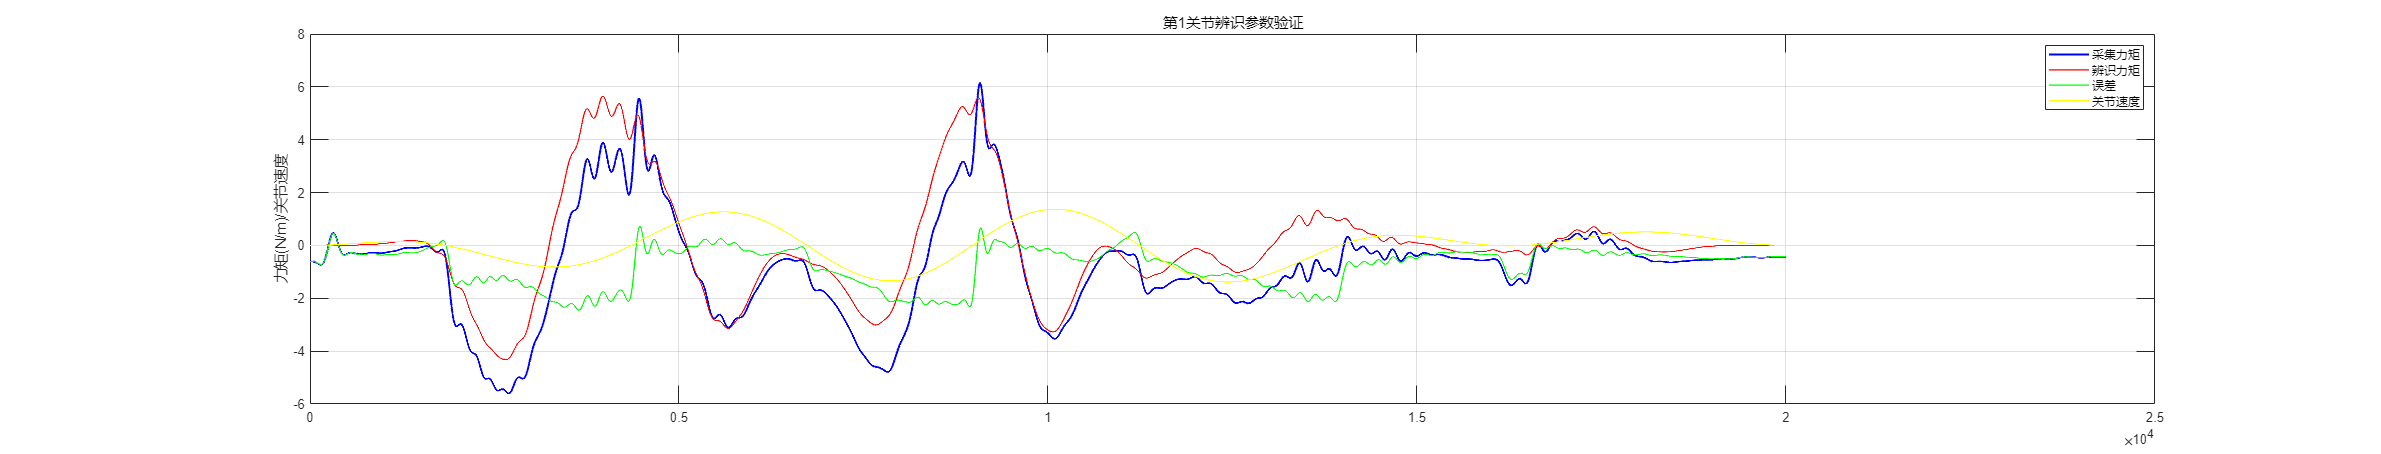

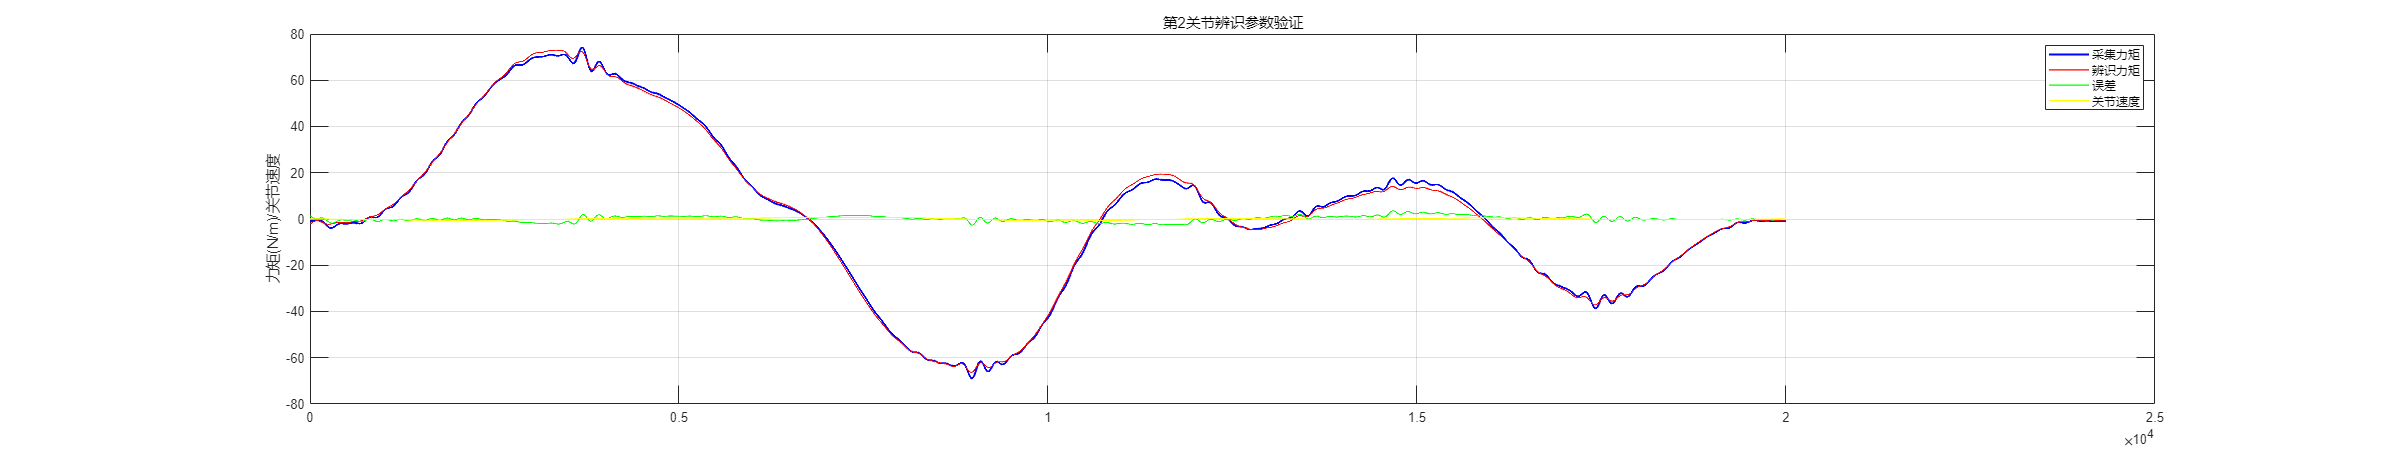

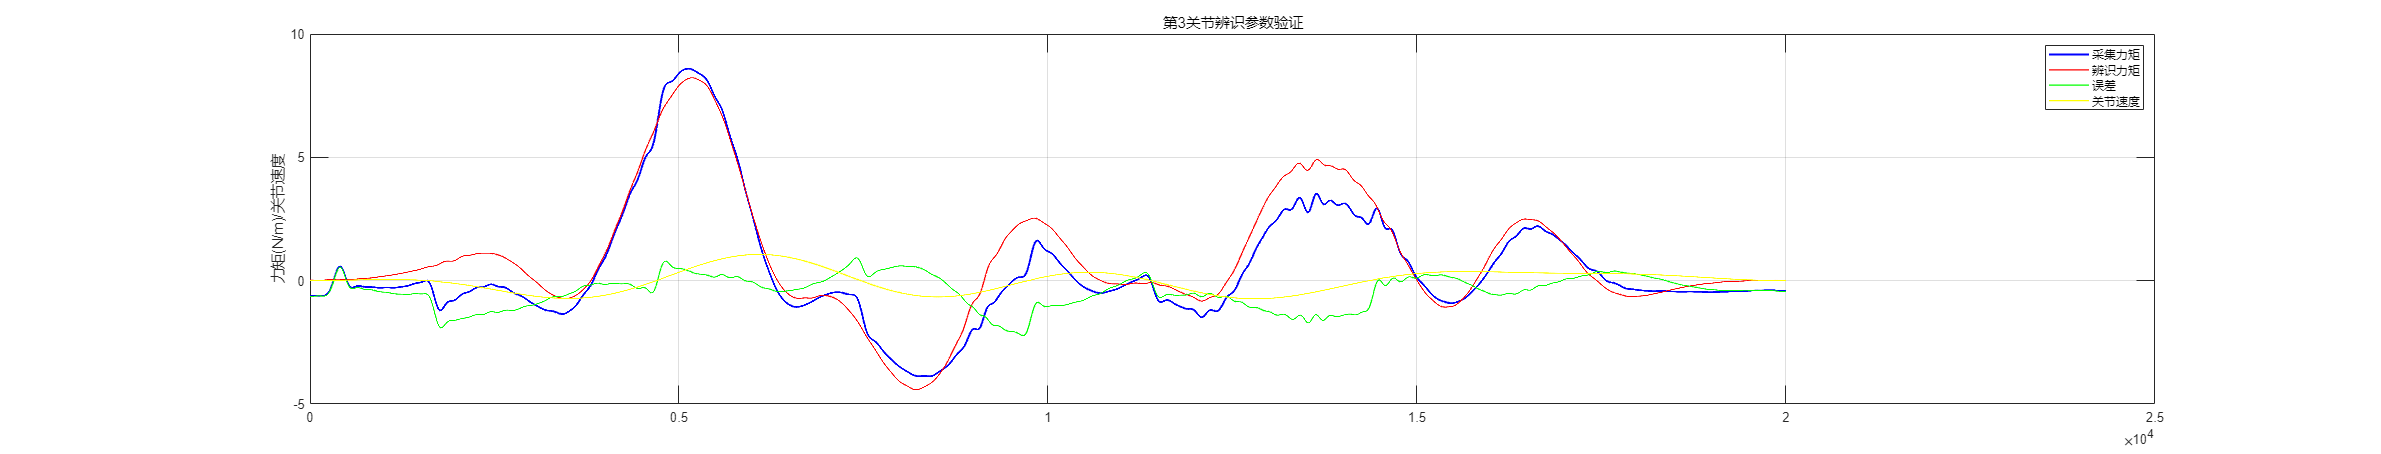

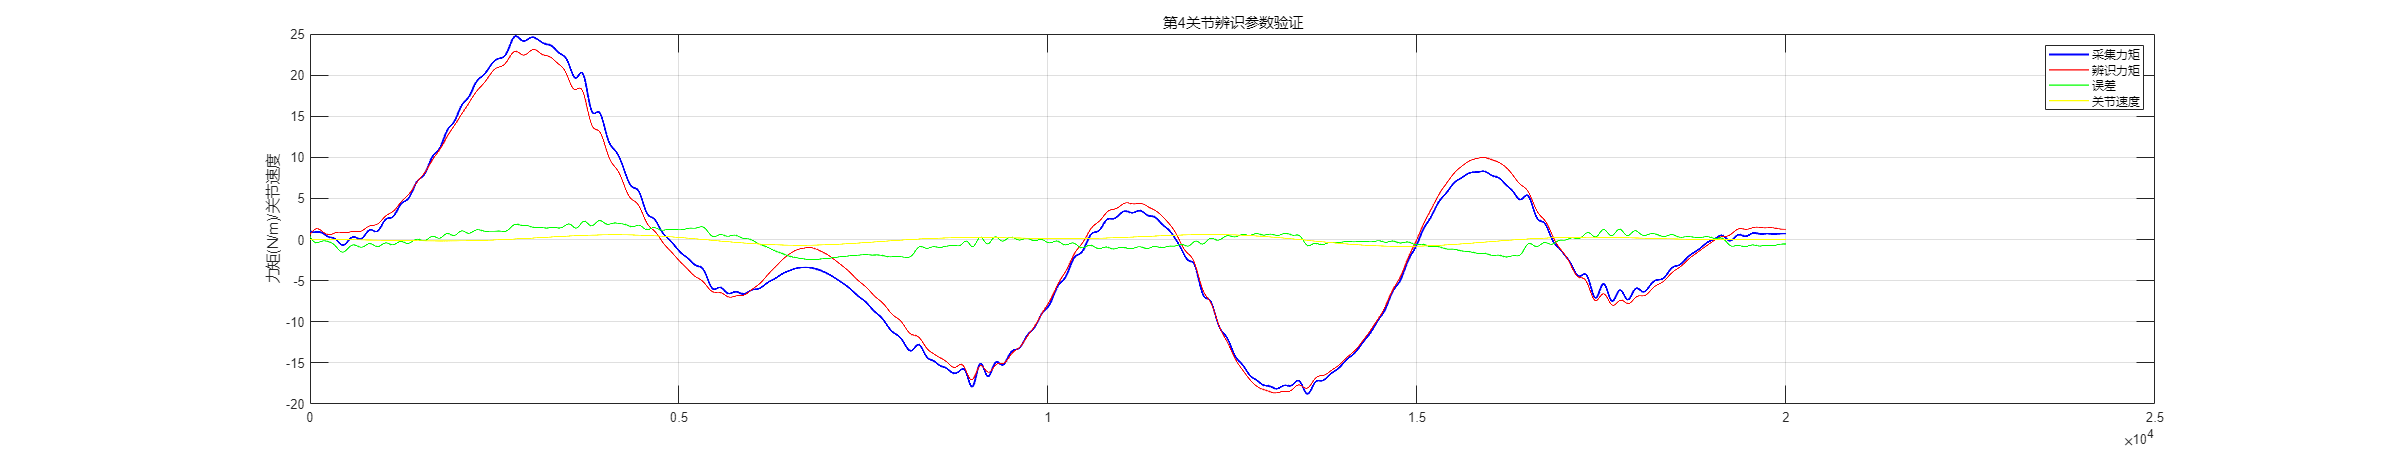

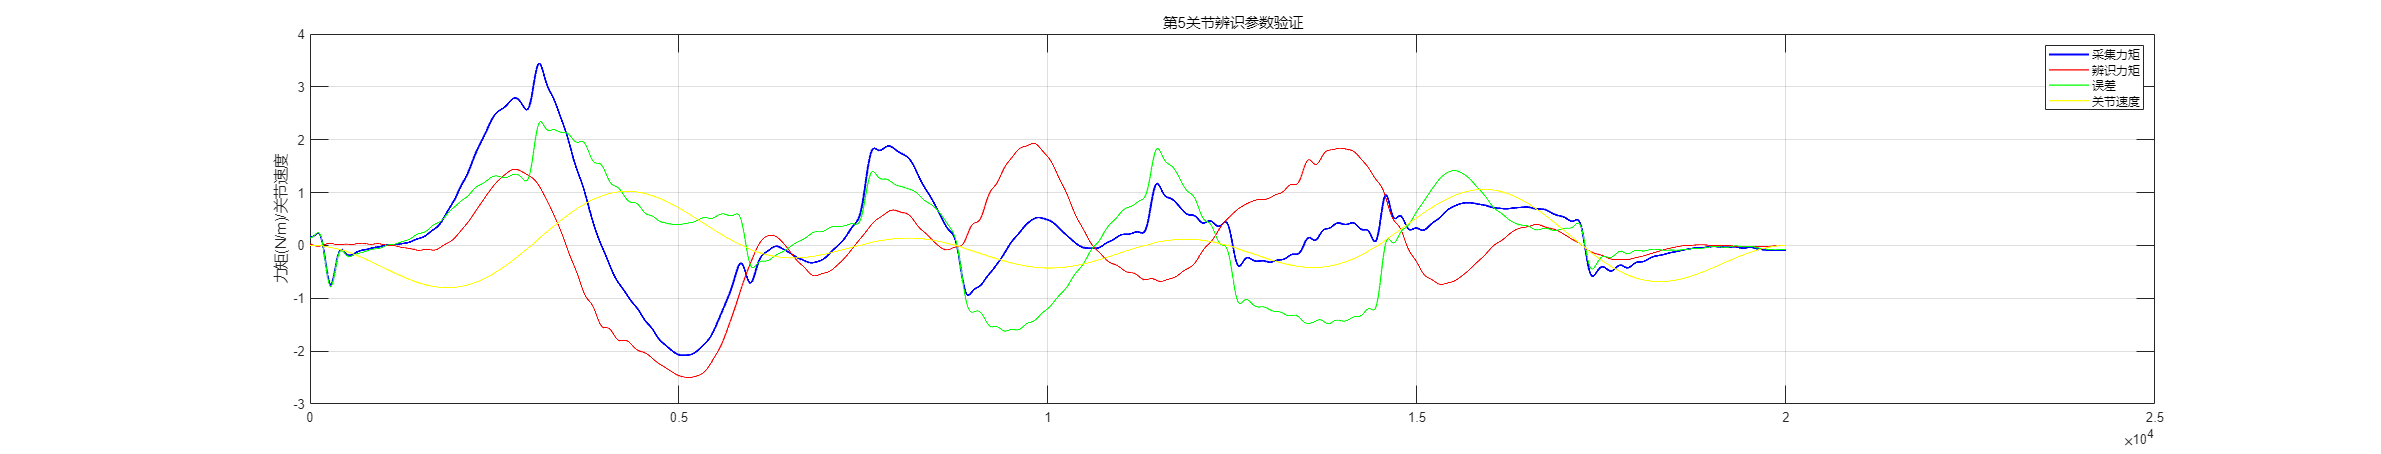

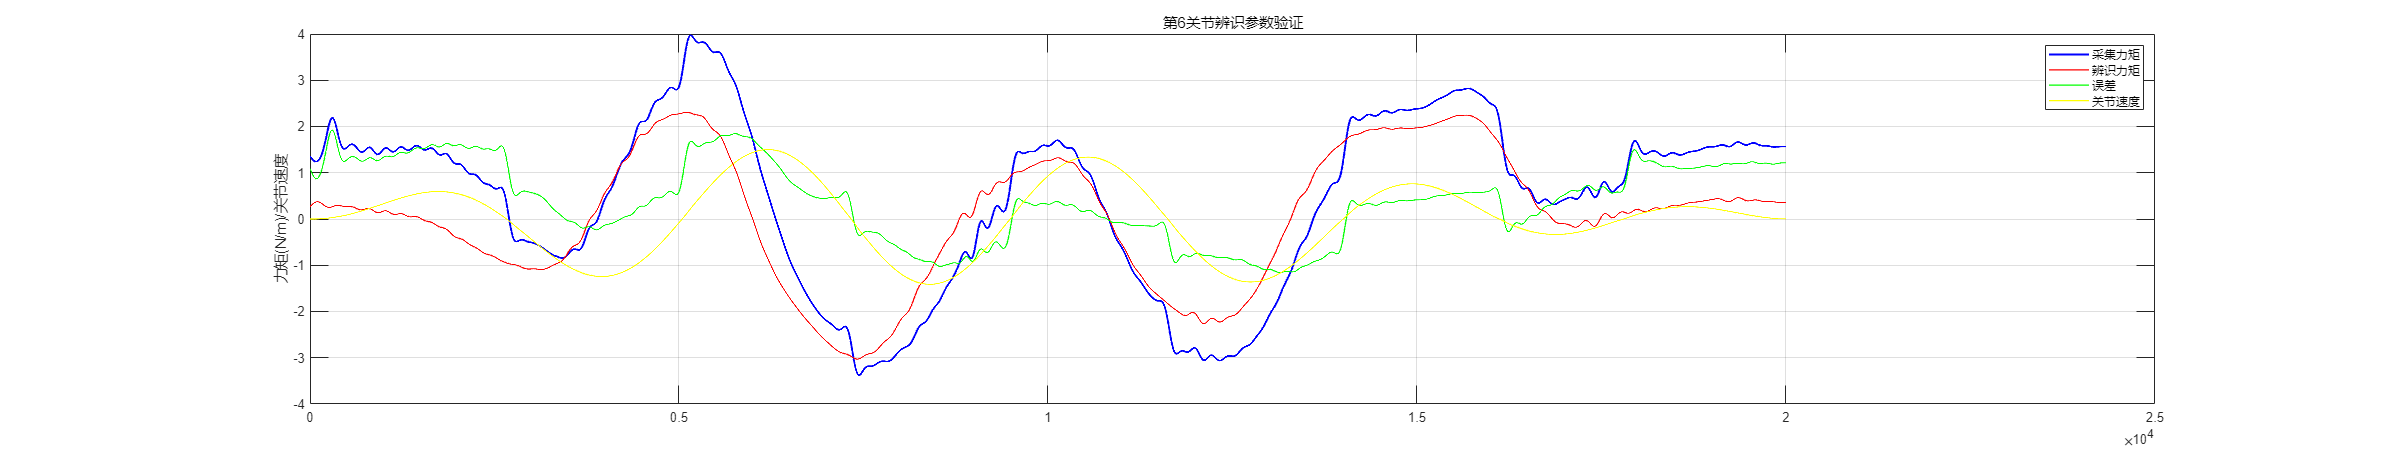

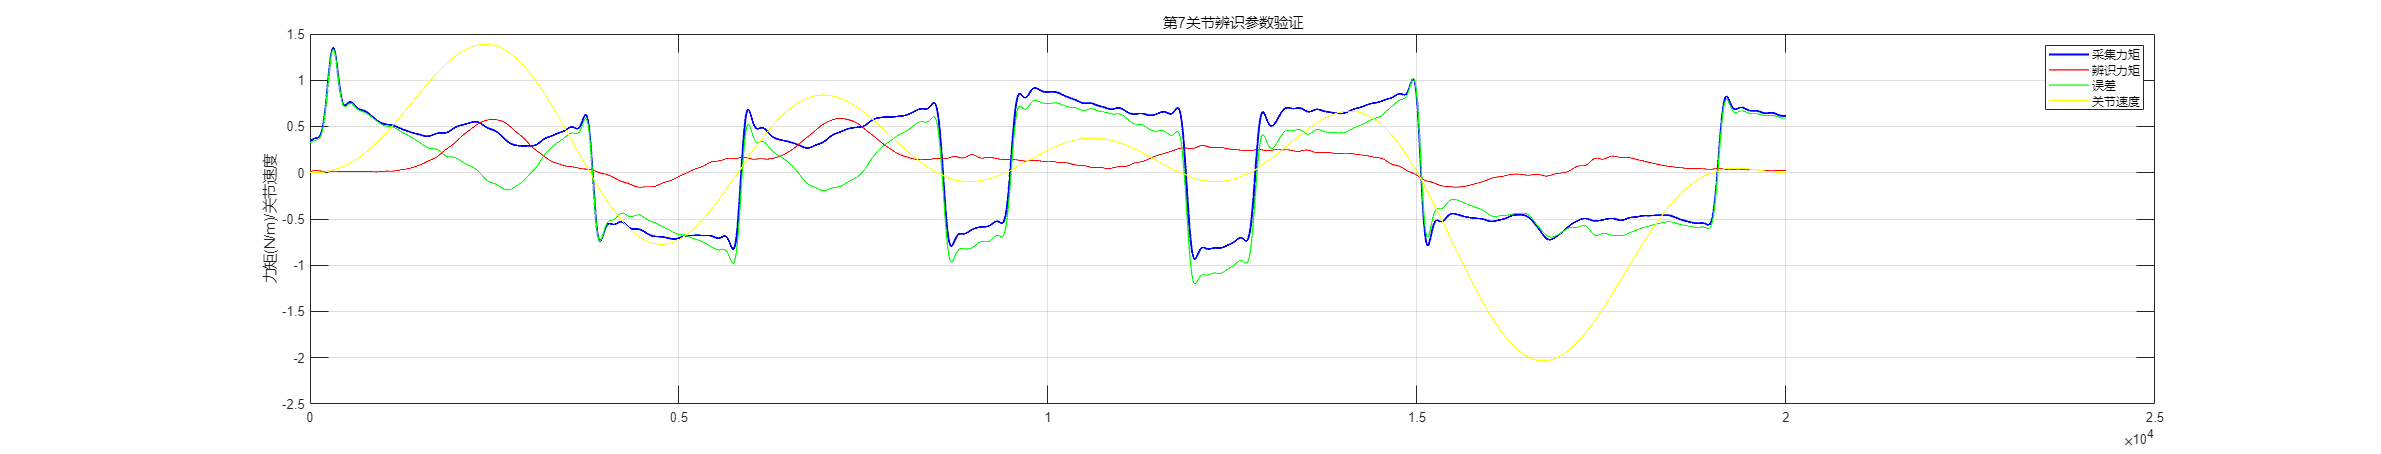

verify_first_step;

## 第二步：辨识摩擦力模型

two_step_identify_script;


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<<a href = "

## 第二步：后处理

friction_identified = compute_Stribeck_friction (qd_filt, opt_x2, 2);
error = error_for_friction - friction_identified;

## 第二步：验证

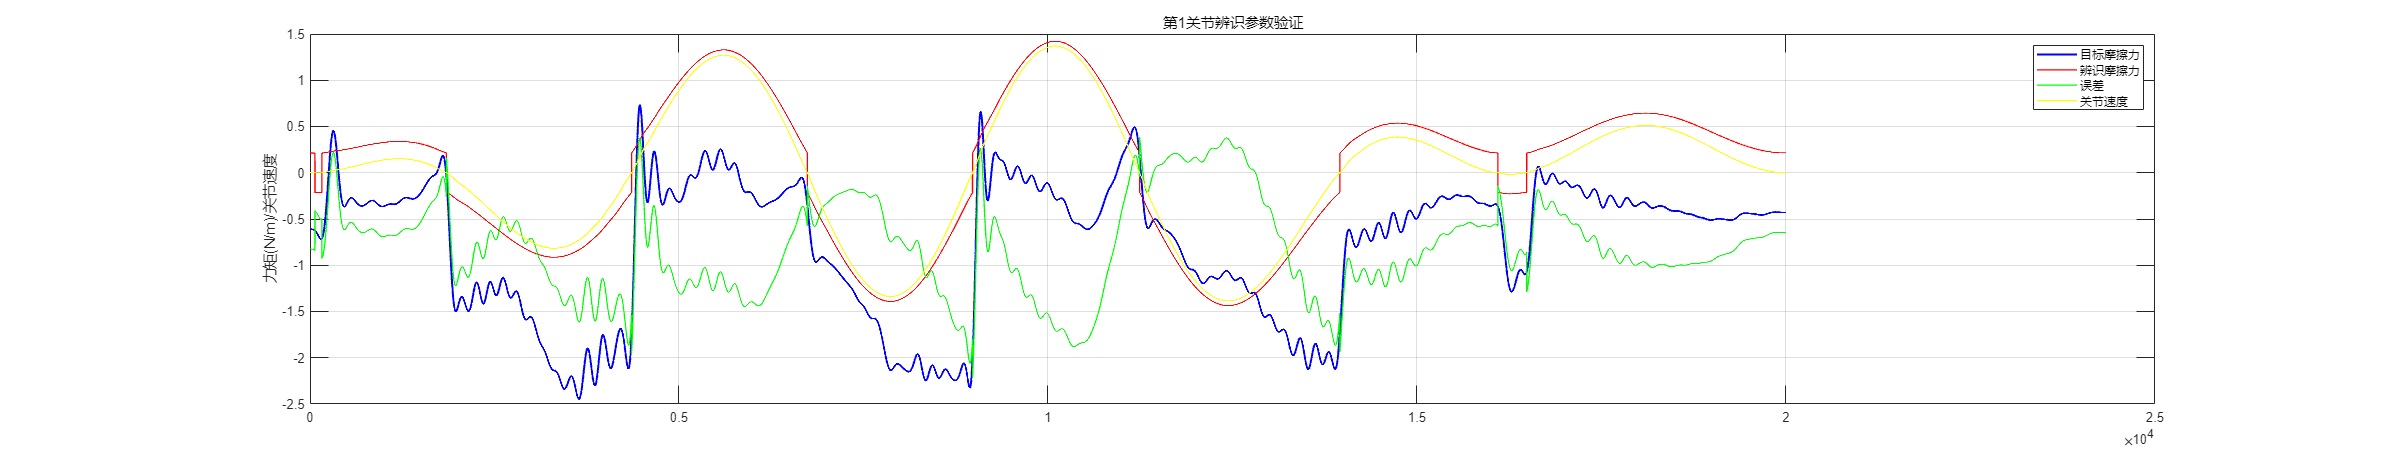

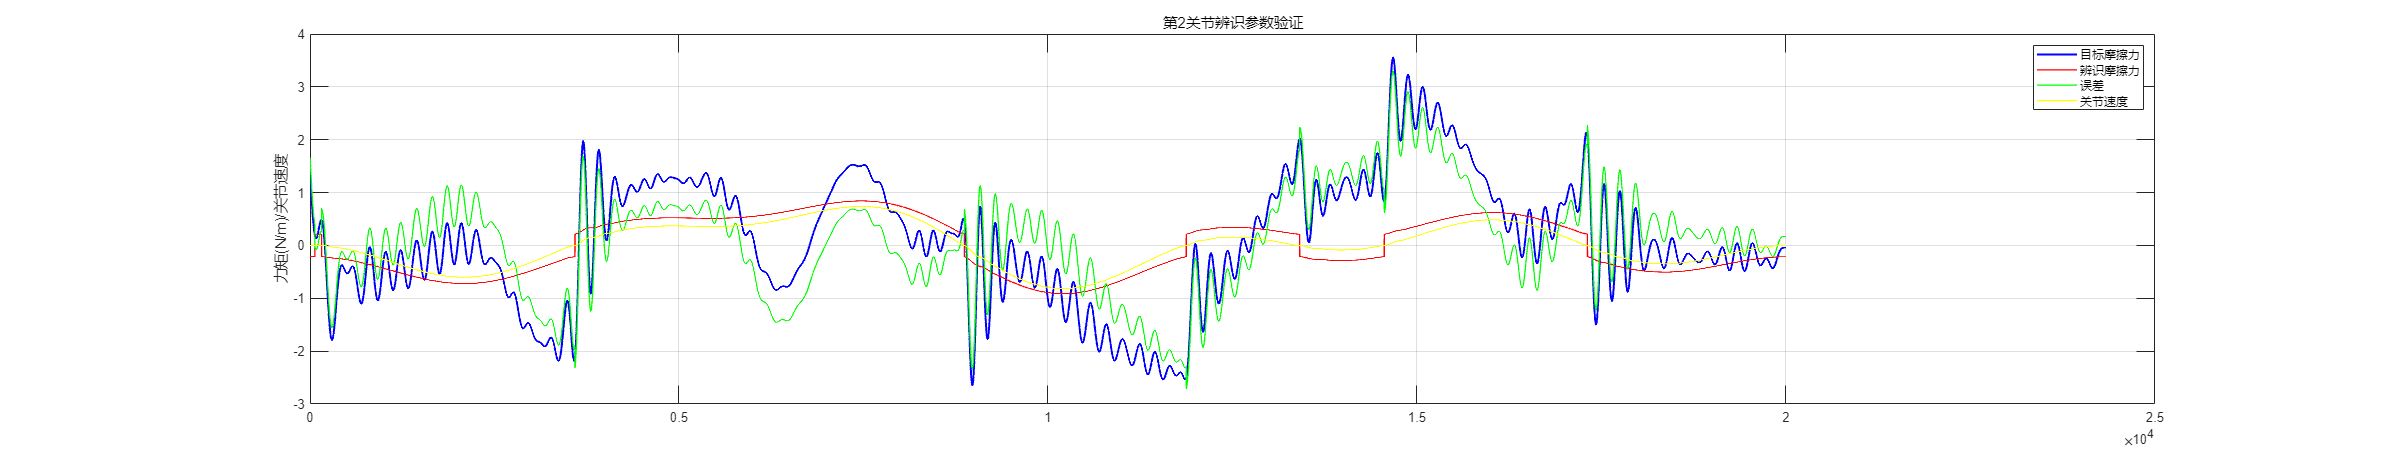

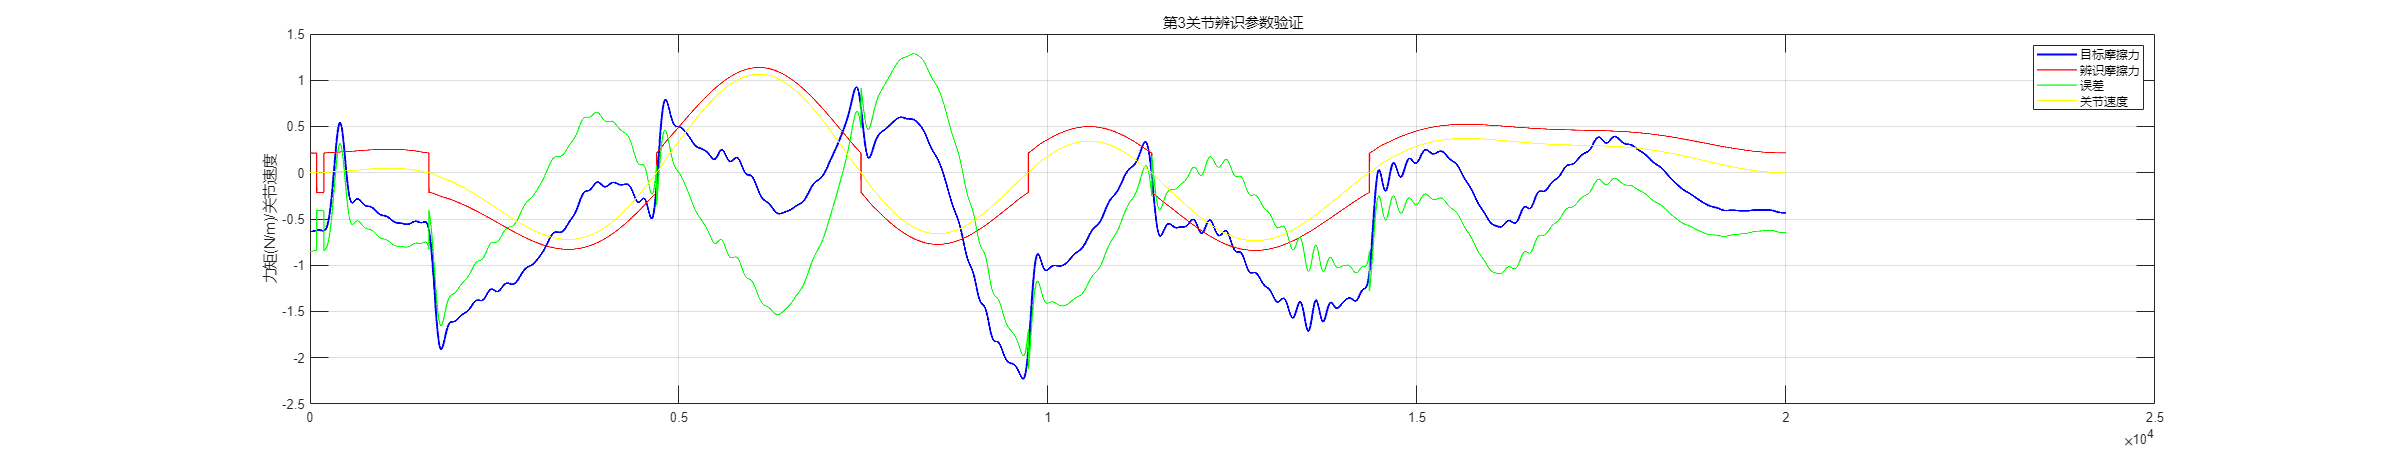

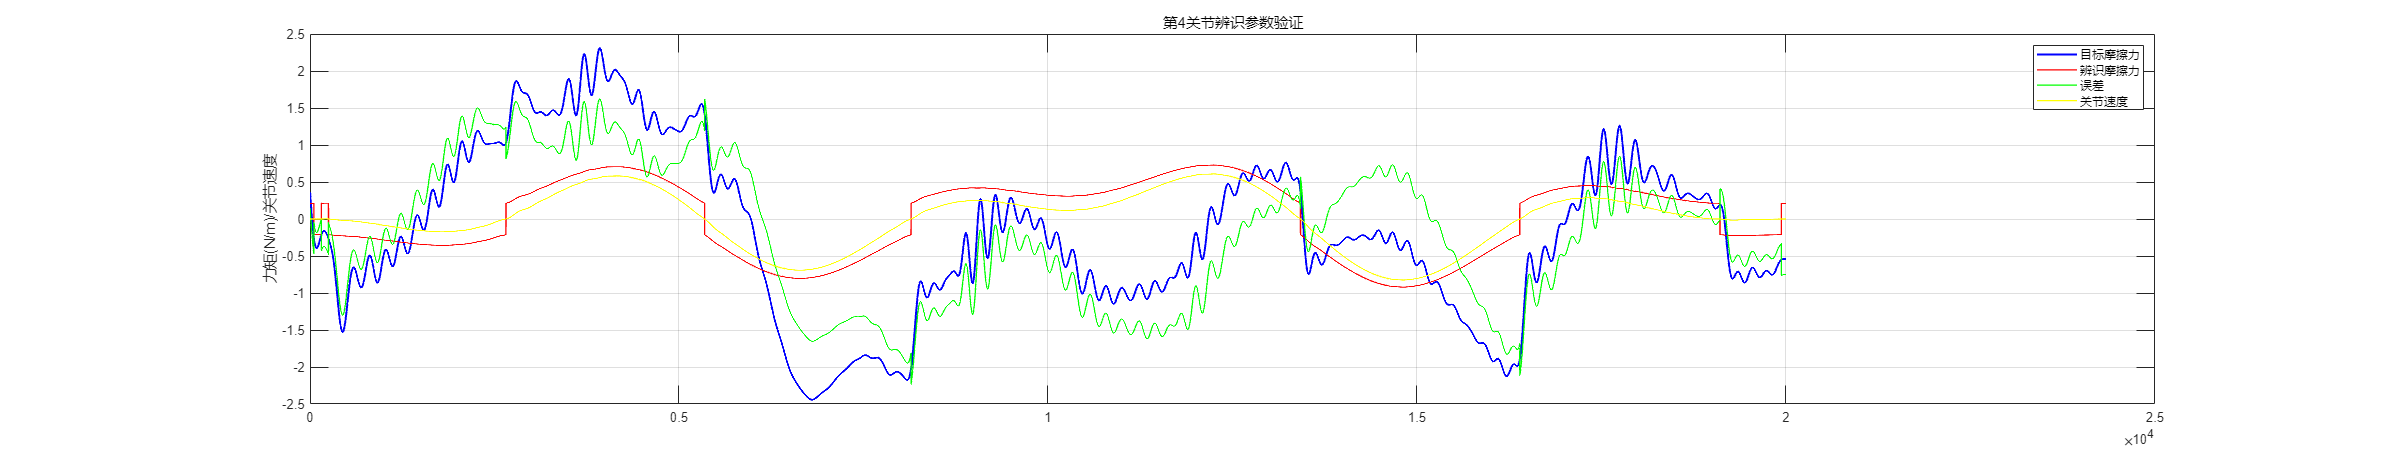

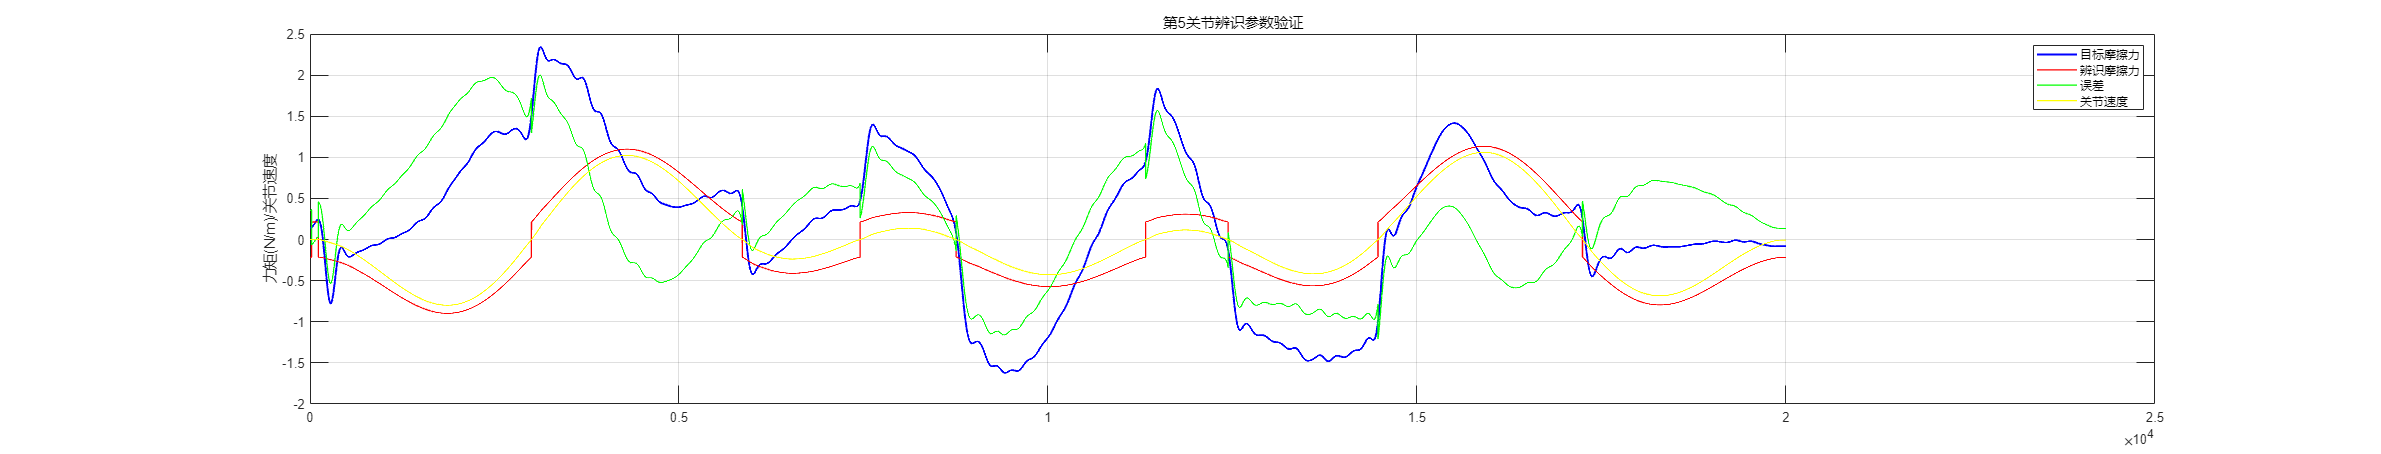

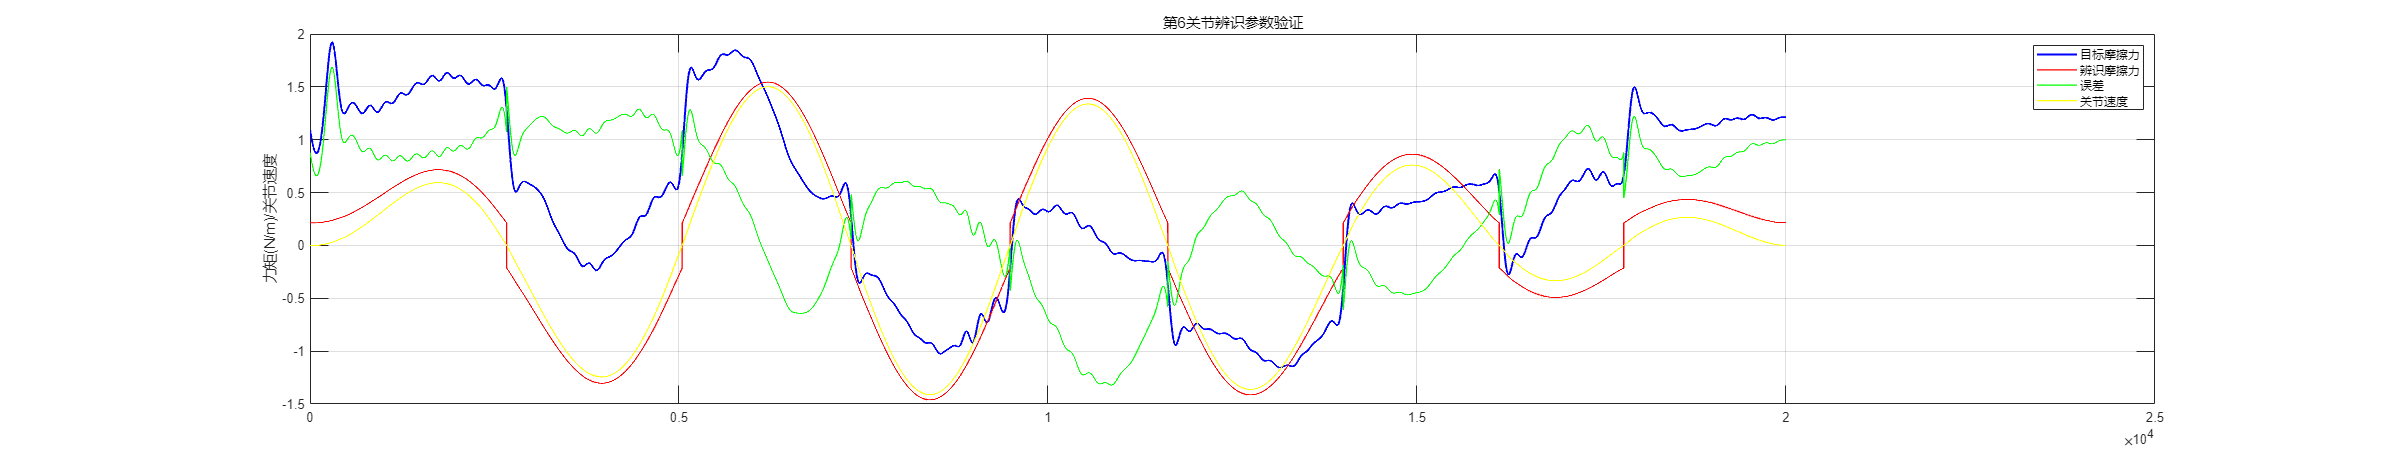

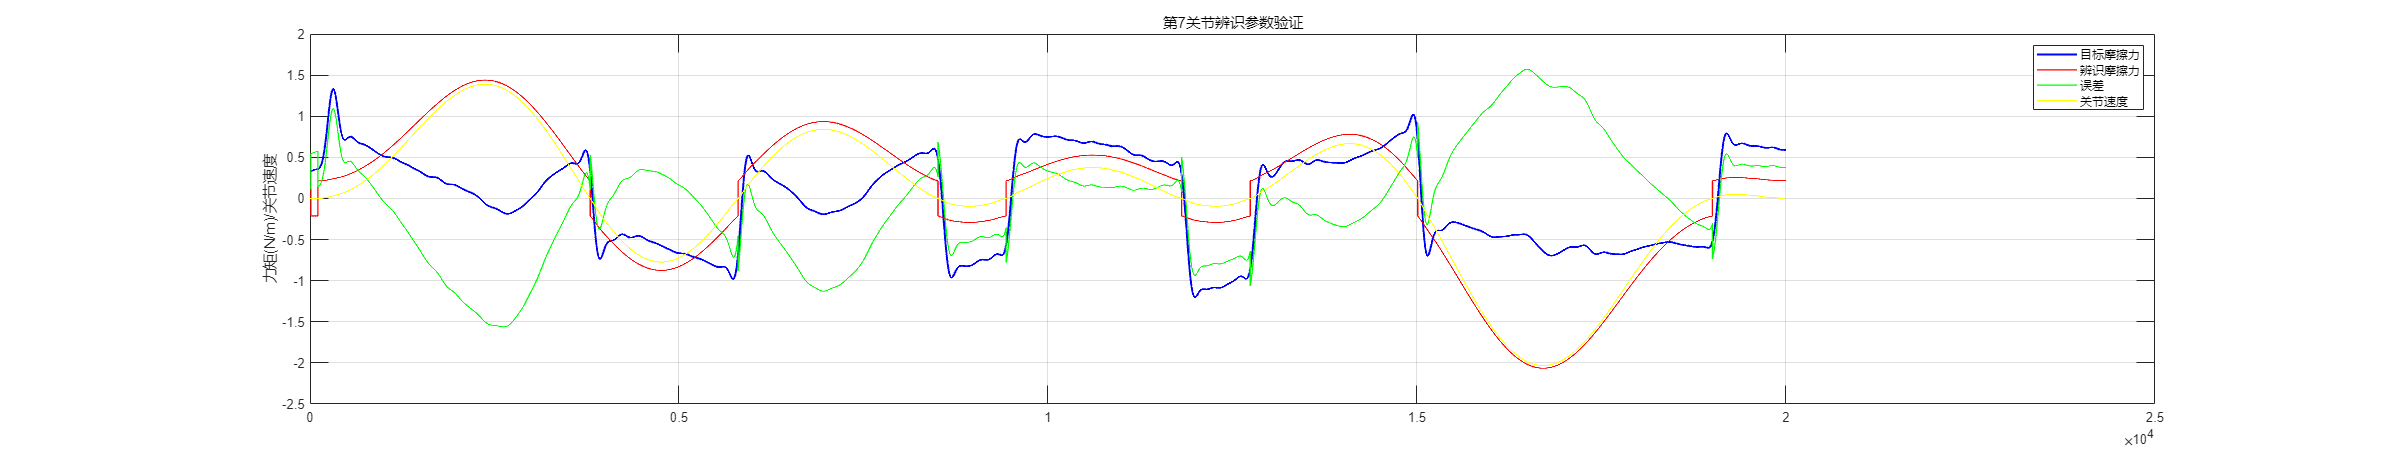

verify_second_step;

## 第三步：整体效果验证

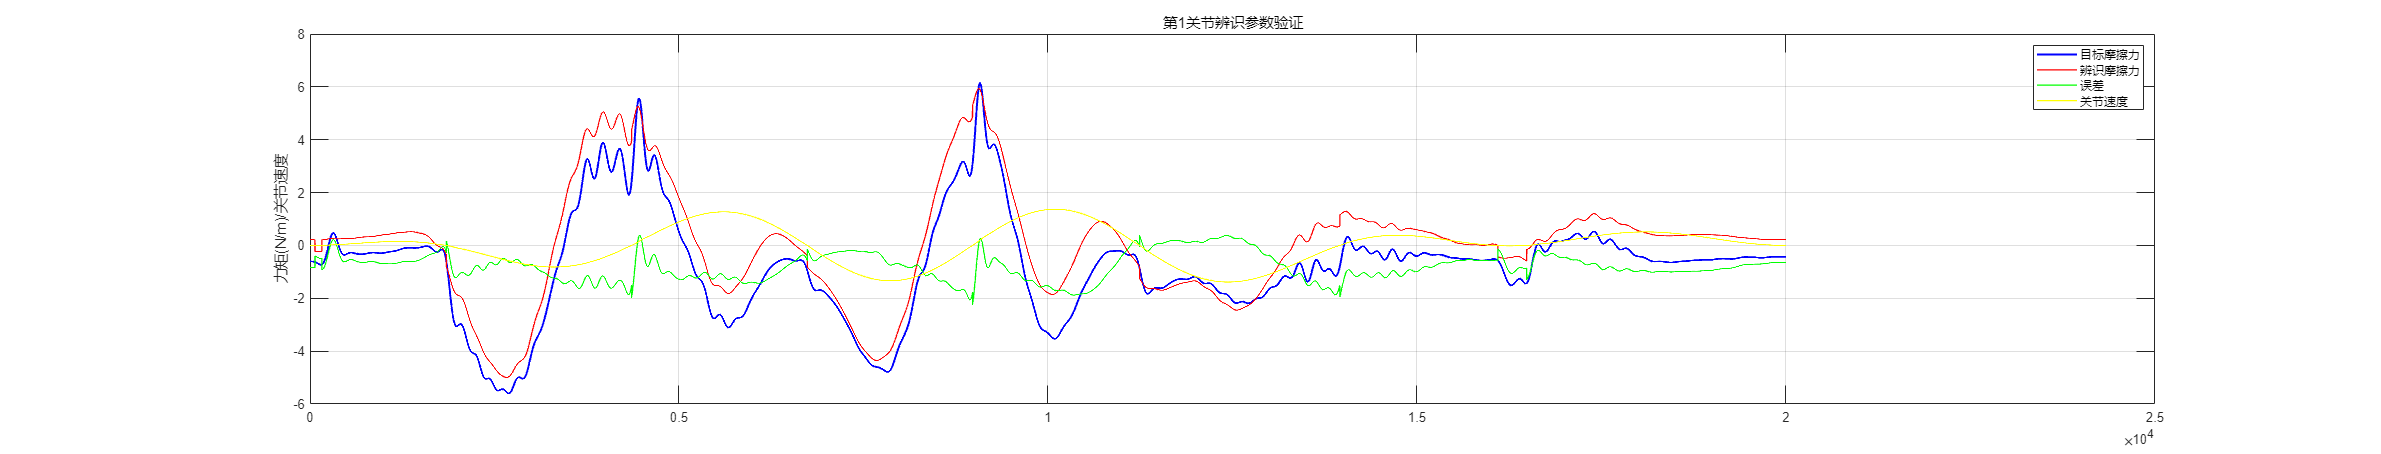

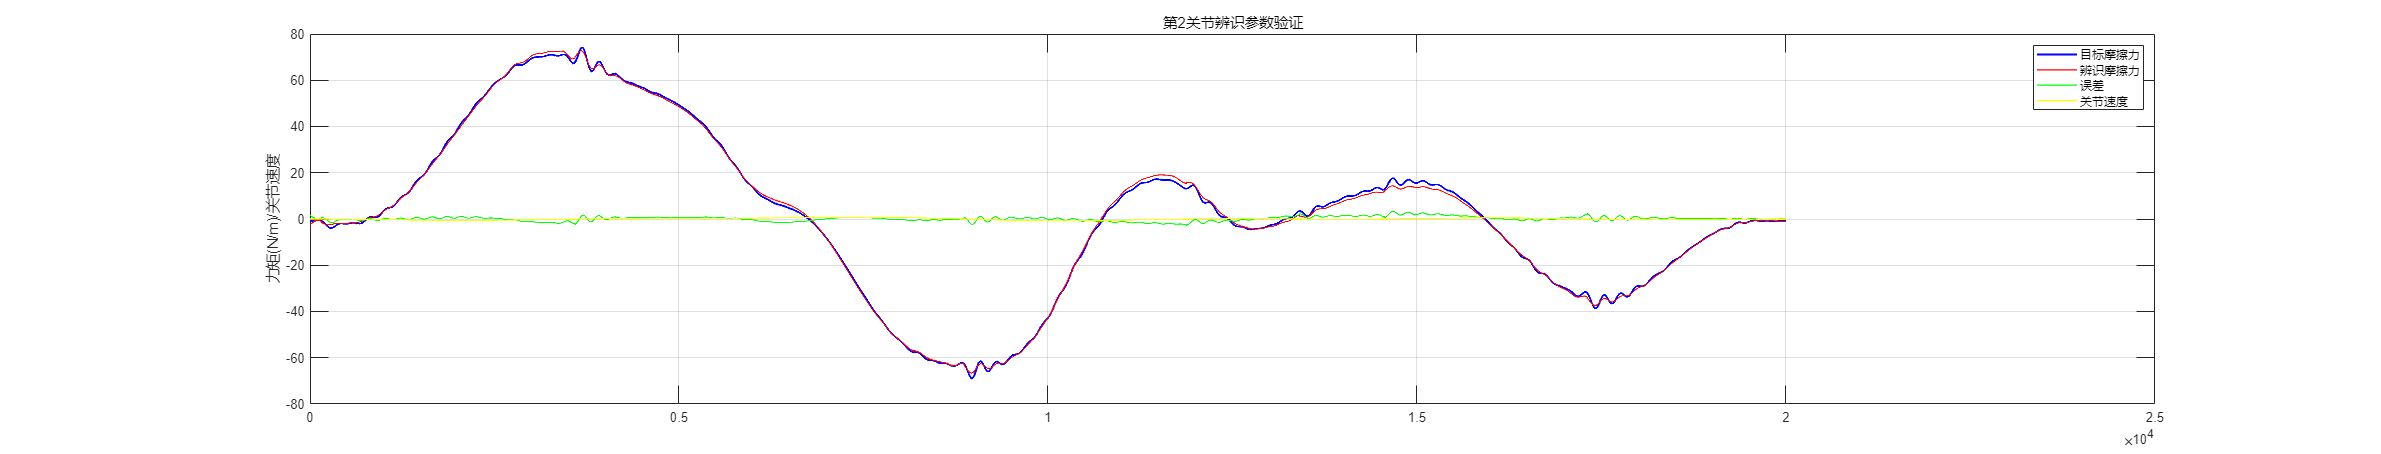

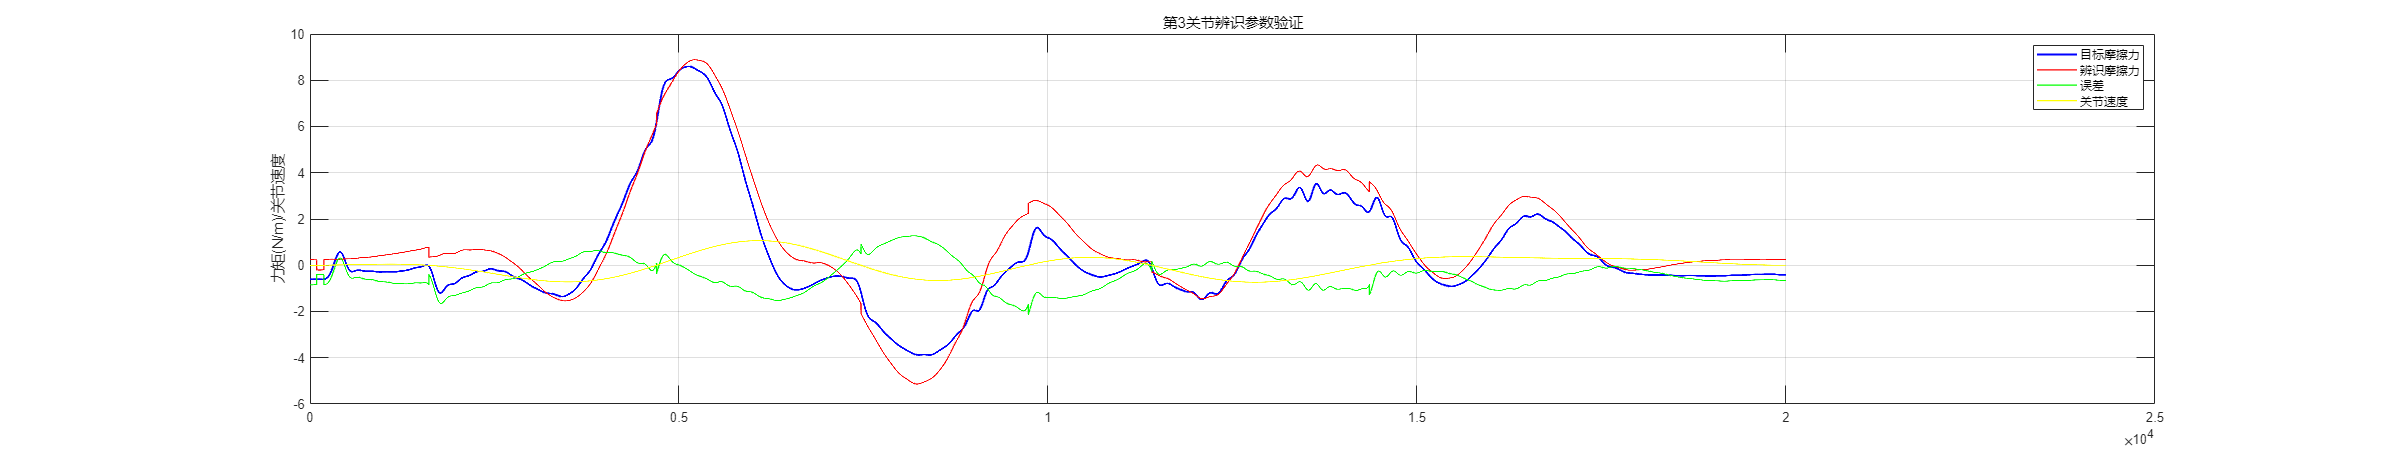

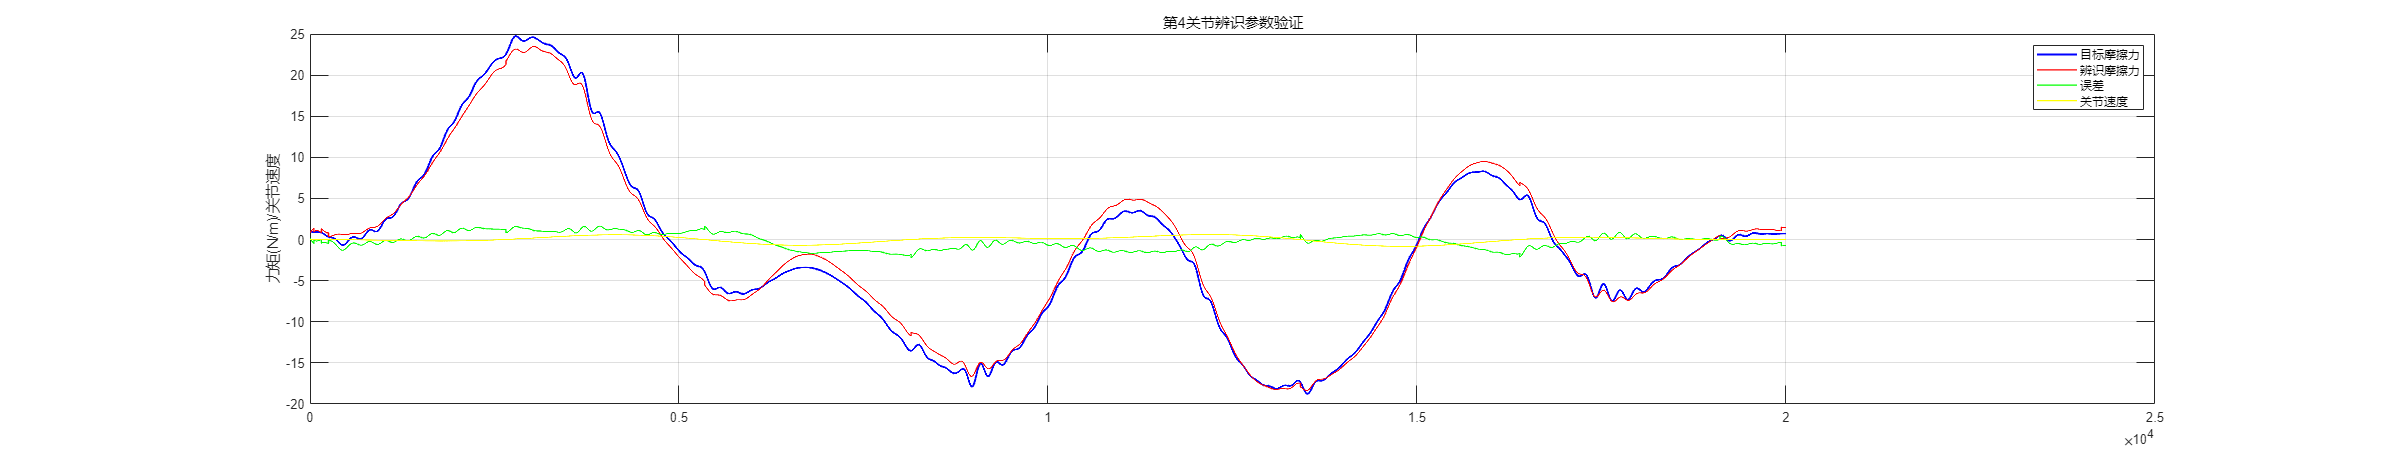

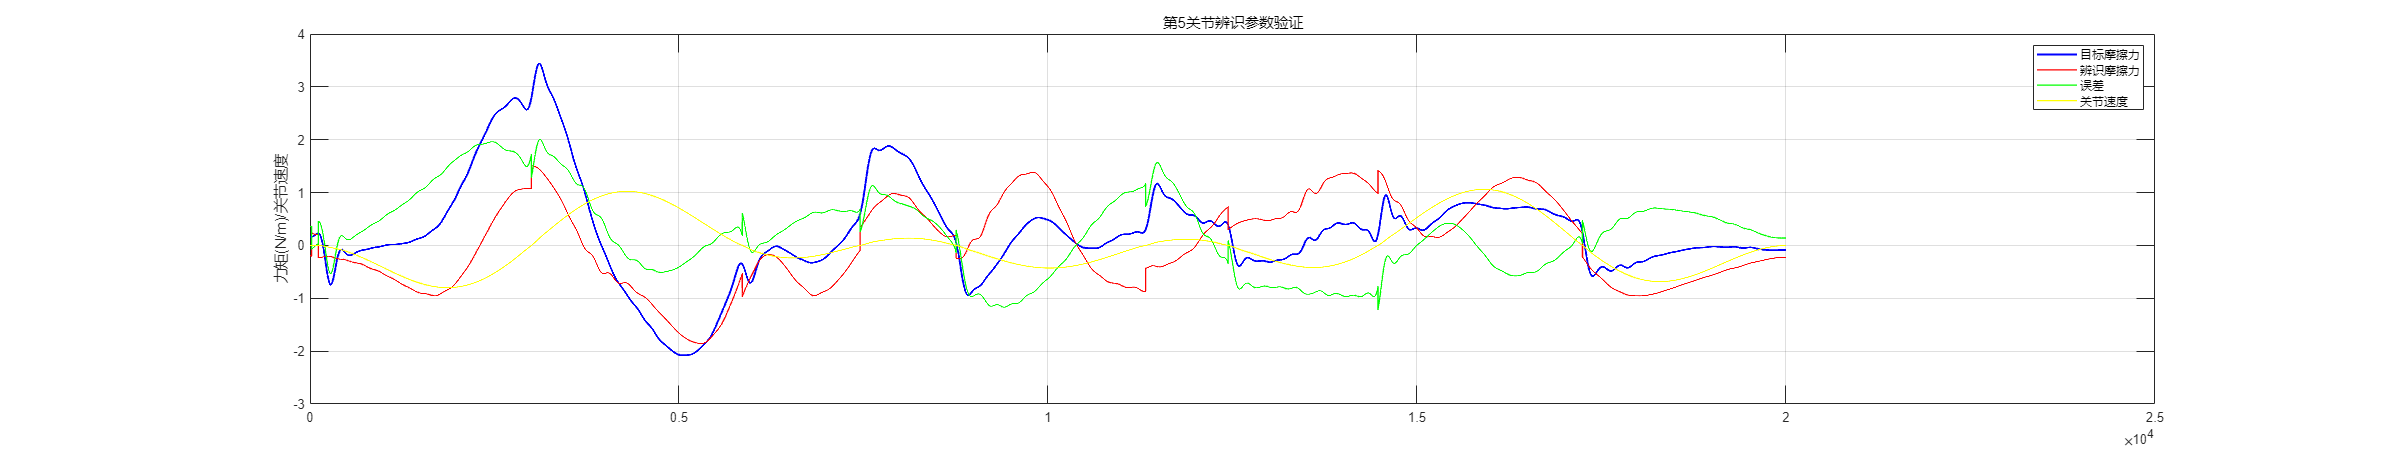

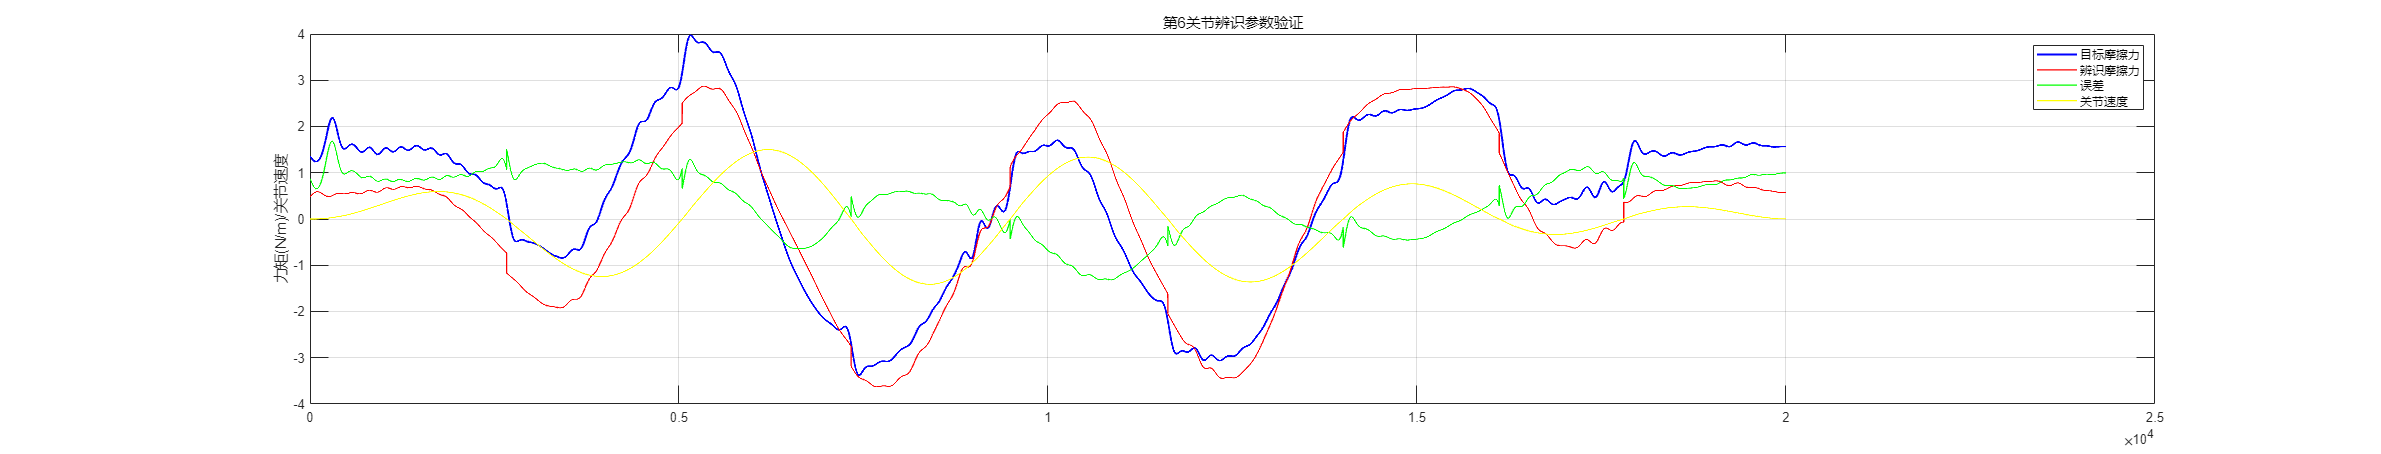

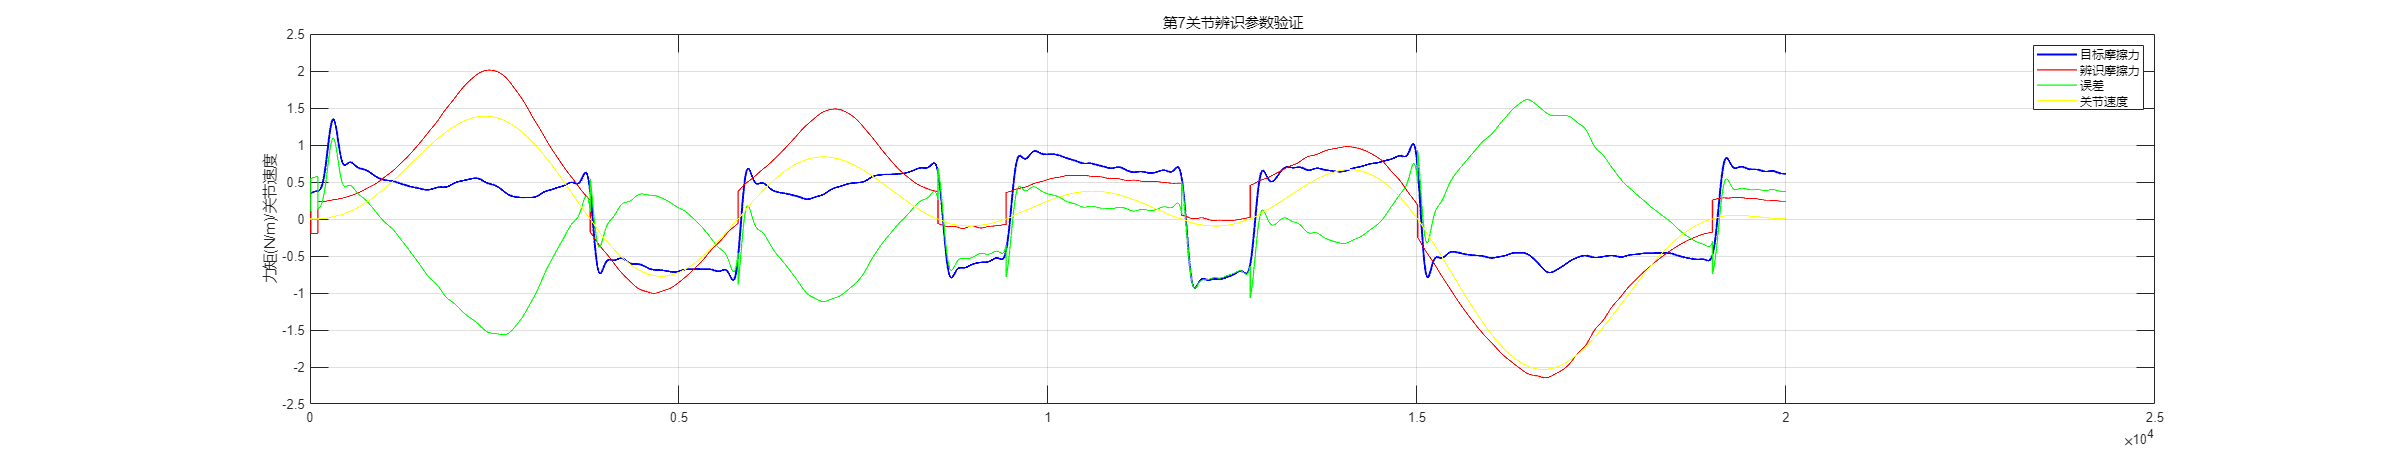

torque_identified_total = torque_identified + friction_identified;
verify_third_step;